# ECMOR-2022

## Introduction

bound = [0,1];

genK = @(N) genField(N+1, 1e-4, 1e-3, 0.1, 0.4); % non-uniform

calcG = @(u) [1 + 0.5 * u.^2, u];

genBC_val = @(N) genField(N+2, 0, 10,0.1, 0.1); % initial and boundary

gen_q_pos = @(k) (-4)^(k) * (rand()-0.5)^(2*k+1)+0.5;

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 0,...
    'tol_rel_g', 0 ...
    );

nlin_newton = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param);

### FOM

Nx = 5000;
dx = 1/Nx;

K = genK(Nx);
q_pos = gen_q_pos(1);
q_val = 2;
U0 = genBC_val(Nx);
x0 = U0(2:end-1);

D.val = K; D.model = calcG;

BC = genBC(1,[U0(1),U0(end)]);

Q.pos = round(Nx*q_pos); Q.val = sparse(Q.pos,1,q_val,Nx,1);

param = genParam(D,BC,Q);

makeFOM = @(name) genProblem(name,Nx,param,x0);
makeROM_I = @(name, encoder) genProblem(name,Nx,param,x0,encoder);
makeROM_II = @(name, encoder, nfa_res,nfa_jac) genProblem(name,Nx,param,x0,encoder,nfa_res,nfa_jac);

FOM = makeFOM('FOM');

Nt = 100;
FOM = solveDif(1,Nt,FOM, nlin_newton);

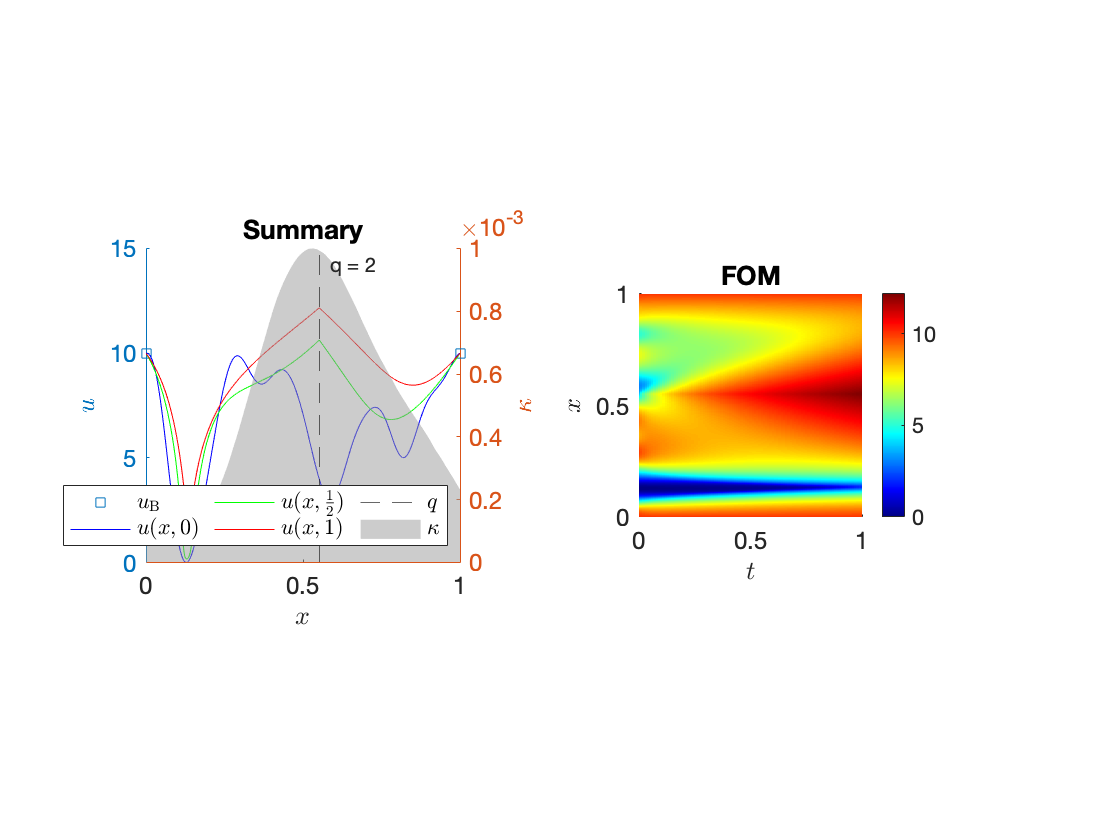

plotSol(figure(),FOM,12);

### ROM-I

#### PCA

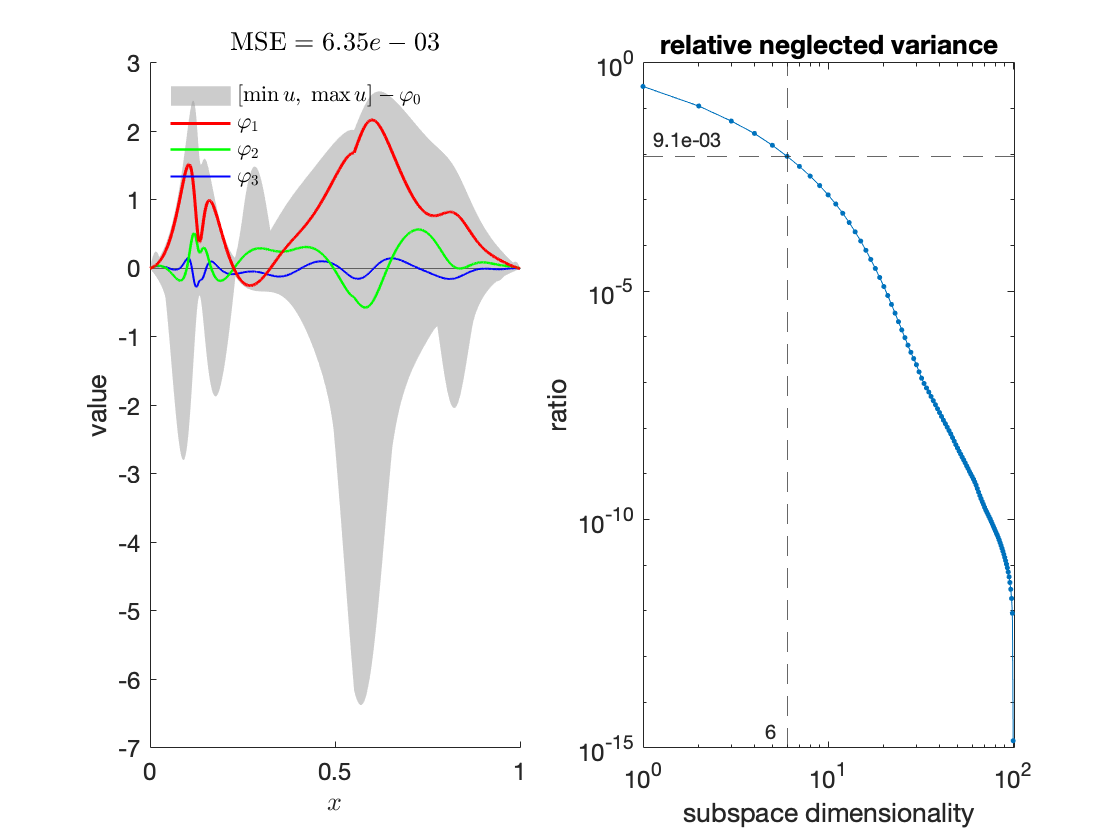

POD = PCA(FOM.X, 1e-2).plotSummary(figure(),'FontSize',12, 'layout','separate');

#### Simulation

ng_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 0,...
    'tol_rel_g', 1e-3 ...
    );

ROM_I = makeROM_I('ROM-I', POD.genEncoder());
nlin.gauss = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD.genEncoder().decjac);

ROM_I = solveDif(1,Nt,ROM_I,nlin.gauss);
ROM_I.X = POD.decode(ROM_I.X);

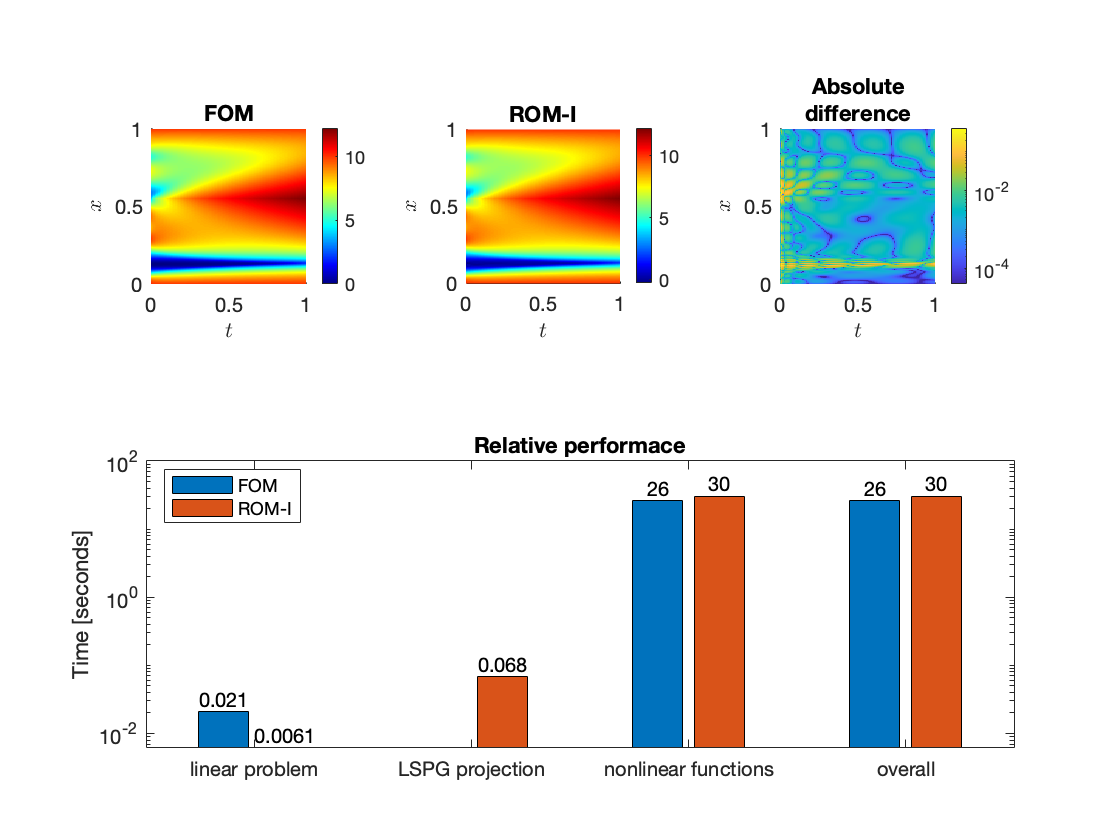

plotComp(figure(),FOM,ROM_I, 10);

### ROM-II

#### Gappy-POD Data

[~,W,Jw,~] = collectSolData(ROM_I);


$$g(u)$$


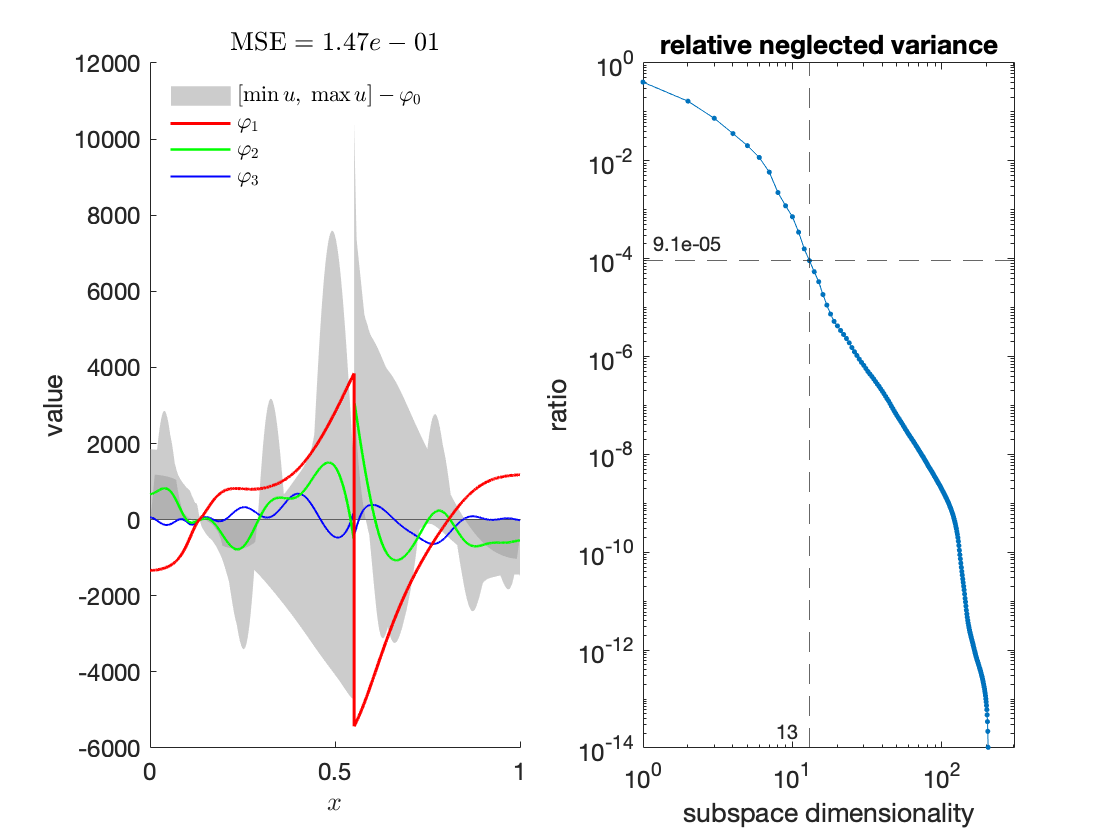

POD_g = PCA(W, 1e-4,'init',zeros(Nx+1,1)).plotSummary(figure(),'FontSize',12, 'layout','separate');


$$g'(u)$$


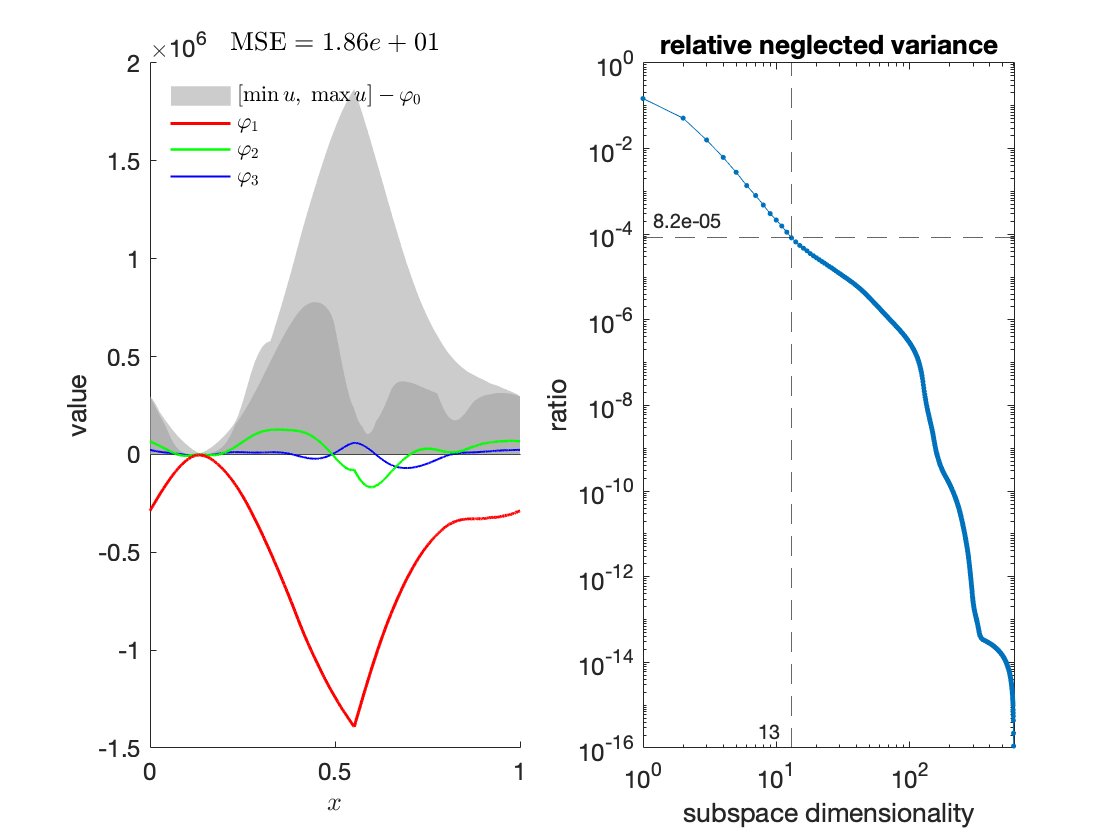

POD_jg = PCA(Jw, 1e-4,'init',zeros(Nx+1,1)).plotSummary(figure(),'FontSize',12, 'layout','separate');

#### Gappy measurement mask

idx = POD_g.calcGreedy(POD_g.npc());
idx_res = idx;
idx = [idx,POD_jg.calcGreedy(POD_jg.npc())];
idx = [idx,POD_jg.calcGreedy(POD_jg.npc())];
idx = [idx,1,Nx+1,Q.pos];
idx = unique(idx);

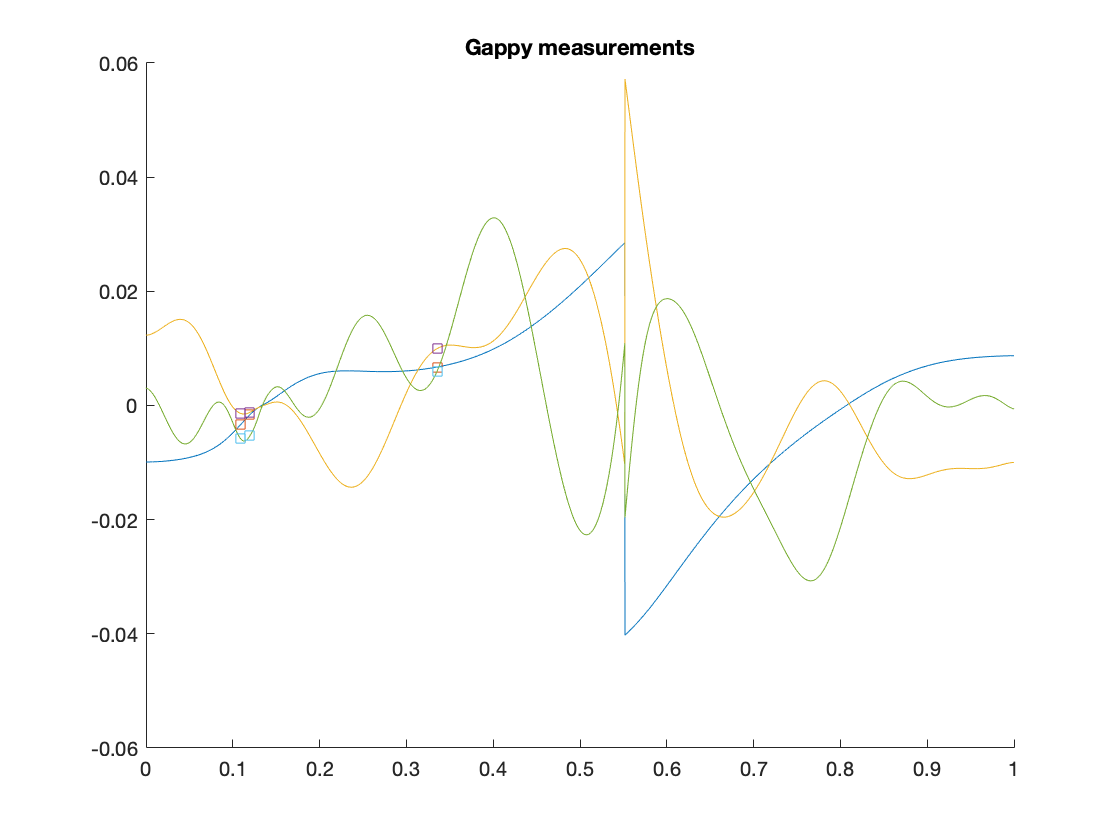

coords = linspace(0,1,Nx+1);
Npc = 3;
idx_disp = idx_res(1:Npc);
figure;
hold on;
for npc = 1:Npc
plot(coords,POD_g.u(:,npc));
scatter(coords(idx_disp),POD_g.u(idx_disp,npc),'s');
end
title('Gappy measurements');
hold off;

POD_g = POD_g.buildGappy(idx);
POD_jg = POD_jg.buildGappy(idx);

#### Simulation

ROM_II = makeROM_II('ROM-II',POD.genEncoder(),POD_g.genNFA(),POD_jg.genNFA());
ROM_II = solveDif(1,Nt,ROM_II,nlin.gauss);
ROM_II.X = POD.decode(ROM_II.X);

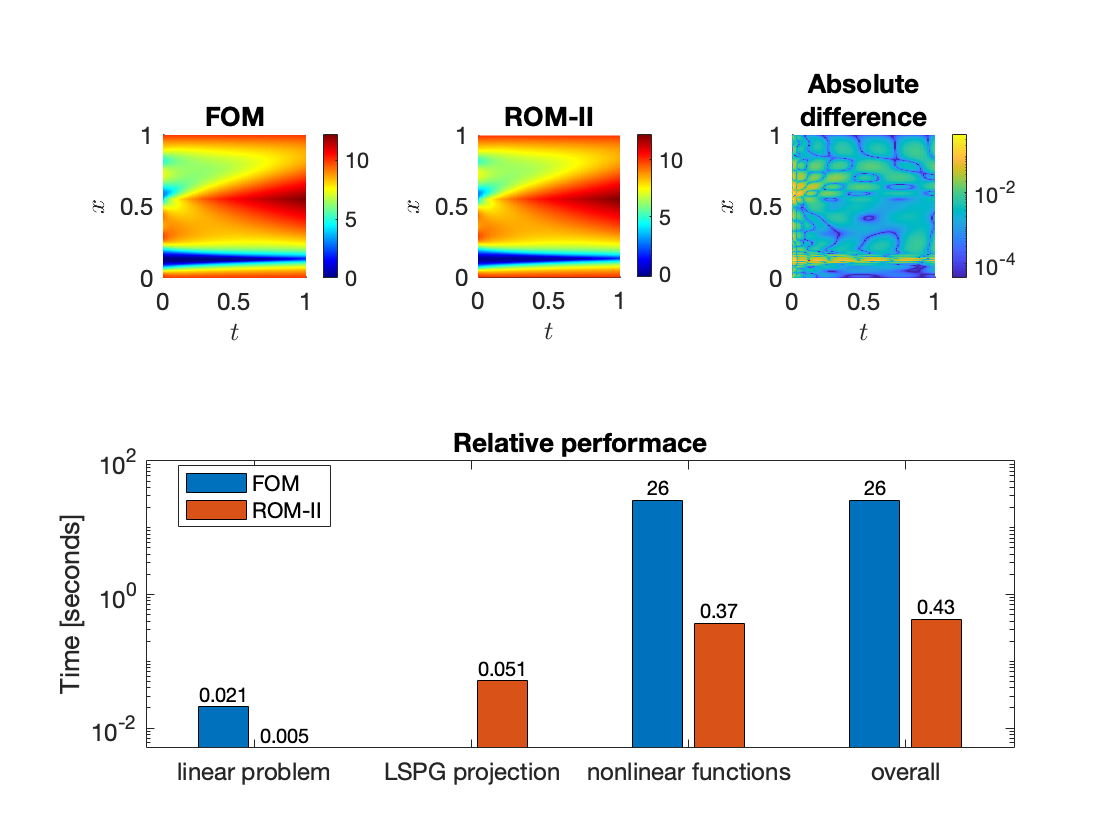

plotComp(figure(),FOM,ROM_II, 12);

### Generalizing ability

#### High

#### Low

## Method 1

### POD basis for different x_q

### Domain decomposition and mapping

### Zero-order approach

### Domain-wise POD performance